clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[9.737;20.673;21.532];
u31=[-0.237;-0.505;0.830];
r2=[11.802;12.458;15.185];
u32=[0.237;-0.505;-0.830];
r3=[20.332;3.972;9.293];
u33=[-0.237;0.505;0.830];
r4=[20.332;20.403;9.293];
u34=[-0.237;0.505;0.830];
r5=[18.982;28.618;27.424];
u35=[0.237;0.505;-0.830];
r6=[18.982;12.188;27.424];
u36=[0.237;0.505;-0.830];


x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
% center and direction of spheroids

hold on
axis([0 10 0 10]);
for R3=1:1:10 %离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =    10.2000    1.0000    1.0017


ans =     9.0000    2.0000    1.0005


ans =     7.7500    3.0000    1.0001


ans =     6.5000    4.0000    1.0076


ans =     5.5000    5.0000    1.0080


ans =     4.7500    6.0000    1.0005


ans =     4.0500    7.0000    1.0013


ans =     3.3500    8.0000    1.0012


ans =     2.6000    9.0000    1.0014


ans =     1.7500   10.0000    1.0093



values1 = spcrv([[x1(1) x1 x1(end)];[y1(1) y1 y1(end)]],3);
plot(values1(1,:),values1(2,:),'color',[29, 50, 67]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[142, 152, 161]/256, ...
    'DisplayName','1-2');

for R3=0.8:0.5:10 %离心率
    R1=7;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3]; 
end

ans =    11.9100    0.8000    1.0004


ans =     7.8000    1.3000    1.0016


ans =     7.2300    1.8000    1.0015


ans =     7.0300    2.3000    1.0001


ans =     6.9300    2.8000    1.0002


ans =     6.8700    3.3000    1.0014


ans =     6.8400    3.8000    1.0001


ans =     6.8100    4.3000    1.0022


ans =     6.8000    4.8000    1.0005


ans =     6.7800    5.3000    1.0029


ans =     6.7800    5.8000    1.0004


ans =     6.7700    6.3000    1.0013


ans =     6.7600    6.8000    1.0027


ans =     6.7600    7.3000    1.0015


ans =     6.7600    7.8000    1.0005


ans =     6.7500    8.3000    1.0026


ans =     6.7500    8.8000    1.0019


ans =     6.7500    9.3000    1.0013


ans =     6.7500    9.8000    1.0008


 
values2 = spcrv([[x2(1) x2 x2(end)];[y2(1) y2 y2(end)]],3);
plot(values2(1,:),values2(2,:),'color',[221, 42, 22]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[238, 148, 138]/256, ...
    'DisplayName','1-5');


for R3=4:1:10 %离心率
    R1=10;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r6,R1,R3,u31,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];  
end

ans =    12.2500    4.0000    1.0013


ans =     8.3500    5.0000    1.0020


ans =     7.3500    6.0000    1.0024


ans =     6.9000    7.0000    1.0019


ans =     6.6500    8.0000    1.0012


ans =     6.4500    9.0000    1.0123


ans =     6.3500   10.0000    1.0110



values3 = spcrv([[x3(1) x3 x3(end)];[y3(1) y3 y3(end)]],3);
plot(values3(1,:),values3(2,:),'color',[191, 144, 0]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[223, 199, 127]/256, ...
    'DisplayName','1-6');

for R3=6:0.8:11 %离心率
    R1=5;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r2,r3,R1,R3,u32,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r2,r3,R1,R3,u32,u33);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];  
end

ans =    10.2300    6.0000    1.0000


ans =     6.4800    6.8000    1.0000


ans =     5.4300    7.6000    1.0015


ans =     4.9300    8.4000    1.0008


ans =     4.6300    9.2000    1.0014


ans =     4.4300   10.0000    1.0028


ans =     4.3000   10.8000    1.0004



values4 = spcrv([[x4(1) x4 x4(end)];[y4(1) y4 y4(end)]],3);
plot(values4(1,:),values4(2,:),'color',[56, 87, 35]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[155, 171, 145]/256, ...
    'DisplayName','2-3');


for R1=6.4:0.2:10.4 %离心率
    R3=2;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.01; %模拟的步长精度

    miu2=cont(r2,r4,R1,R3,u32,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r2,r4,R1,R3,u32,u34);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];  
end

ans =     6.4000   14.4500    1.0000


ans =     6.6000    5.5100    1.0001


ans =     6.8000    4.1300    1.0001


ans =     7.0000    3.4900    1.0001


ans =     7.2000    3.1000    1.0010


ans =     7.4000    2.8400    1.0012


ans =     7.6000    2.6500    1.0014


ans = 1×3
    7.8000    2.5100    1.0003


ans = 1×3
    8.0000    2.3900    1.0017


ans = 1×3
    8.2000    2.3000    1.0006


ans = 1×3
    8.4000    2.2200    1.0014


ans = 1×3
    8.6000    2.1500    1.0033


ans = 1×3
    8.8000    2.1000    1.0006


ans = 1×3
    9.0000    2.0500    1.0012


ans = 1×3
    9.2000    2.0000    1.0051


ans = 1×3
    9.4000    1.9700    1.0011


ans = 1×3
    9.6000    1.9300    1.0049


ans = 1×3
    9.8000    1.9000    1.0052


ans = 1×3
   10.0000    1.8800    1.0010


ans = 1×3
   10.2000    1.8500    1.0048


ans = 1×3
   10.4000    1.8300    1.0035


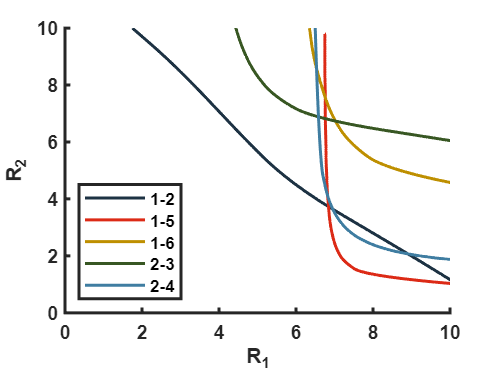


values5 = spcrv([[x5(1) x5 x5(end)];[y5(1) y5 y5(end)]],3);
plot(values5(1,:),values5(2,:),'color',[63, 125, 162]/256, ...
    'LineWidth',1.5,'MarkerSize',1, ...
    'markerfacecolor',[159, 190, 208]/256, ...
    'DisplayName','2-4');


set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_2','FontName','arial','FontWeight','bold');
legend('Location','southwest');
hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end

